# **Project:** How does the performance of a Greenpower car change during a race?

I am going to use data from our performance at Dunsfold race on 13/09/2026 to analyse how the performance of Empress (our car) changes during a race.

**Main objectives:**

- See what conclusions can be made about the performance of empress.

- Identify the source of what causes empress to slow down during race.

- Use the data to make the process of looking for solutions that allow empress to maintain speed for as long as possible during races easier.

Display Table:

GreenpowerRaceData_real_ = readtable('Greenpower Dunsfold race data.xlsx');

GreenpowerRaceData_real_

GreenpowerRaceData_real_ = 38×6 table
    LapNumber_1    LapTime_secs__1    LapNumber_2    LapTime_secs__2    TrackDistance_metres_    TotalRaceTime_mins_
    ___________    _______________    ___________    _______________    _____________________    ___________________

         1              119.9              1              116.7                 1210                      90        
         2                465              2              111.3                  NaN                     NaN        
         3              113.3              3              109.5                  NaN                     NaN        
         4              111.2              4              111.5                  NaN                     NaN        
         5              109.7              5           

Import data from table into variables:

lapNumber1 = GreenpowerRaceData_real_.LapNumber_1

lapNumber1 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15


lapTime1 = GreenpowerRaceData_real_.LapTime_secs__1

lapTime1 =   119.9000
  465.0000
  113.3000
  111.2000
  109.7000
  113.2000
  115.2000
  267.9000
  111.6000
  111.5000
  112.7000
  111.9000
  112.8000
  113.8000
  113.7000



lapNumber2 = GreenpowerRaceData_real_.LapNumber_2

lapNumber2 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15


lapTime2 = GreenpowerRaceData_real_.LapTime_secs__2

lapTime2 =   116.7000
  111.3000
  109.5000
  111.5000
  108.9000
  113.9000
  113.9000
  109.3000
  109.6000
  111.9000
  113.7000
  112.4000
  283.5000
  121.3000
  116.6000



lapDistance = GreenpowerRaceData_real_.TrackDistance_metres_

lapDistance =         1210
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN


totalRaceTime = GreenpowerRaceData_real_.TotalRaceTime_mins_

totalRaceTime =     90
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


Calculate Average lap time:

avgLapTime1 = mean(lapTime1(1:34))

avgLapTime1 = 153.0588

avgLapTime2 = mean(lapTime2)

avgLapTime2 = 159.5000

Calculate Fastest lap:

fastestLap1 = min(lapTime1(1:34))

fastestLap1 = 109.7000

fastestLap2 = min(lapTime2)

fastestLap2 = 108.9000

Calculate Slowest lap:

slowestLap1 = max(lapTime1(1:34))

slowestLap1 = 465

slowestLap2 = max(lapTime2)

slowestLap2 = 807.2000

Calculate difference between fastest and slowest lap:

diff1 = slowestLap1 - fastestLap1

diff1 = 355.3000

diff2 = slowestLap2 - fastestLap2

diff2 = 698.3000

Calculate the speed of each lap:

lapDistanceDivider = 1210; % metres

eachLapSpeed1 = lapDistanceDivider./lapTime1

eachLapSpeed1 =    10.0917
    2.6022
   10.6796
   10.8813
   11.0301
   10.6890
   10.5035
    4.5166
   10.8423
   10.8520
   10.7365
   10.8132
   10.7270
   10.6327
   10.6420


eachLapSpeed2 = lapDistanceDivider./lapTime2

eachLapSpeed2 =    10.3685
   10.8715
   11.0502
   10.8520
   11.1111
   10.6234
   10.6234
   11.0704
   11.0401
   10.8132
   10.6420
   10.7651
    4.2681
    9.9753
   10.3774


Calculate Average lap speed:

avgLapSpeed1 = lapDistance(1)/avgLapTime1

avgLapSpeed1 = 7.9055

avgLapSpeed2 = lapDistance(1)/avgLapTime2 

avgLapSpeed2 = 7.5862

Graph to display the time taken for empress to complete each lap in Race 1:

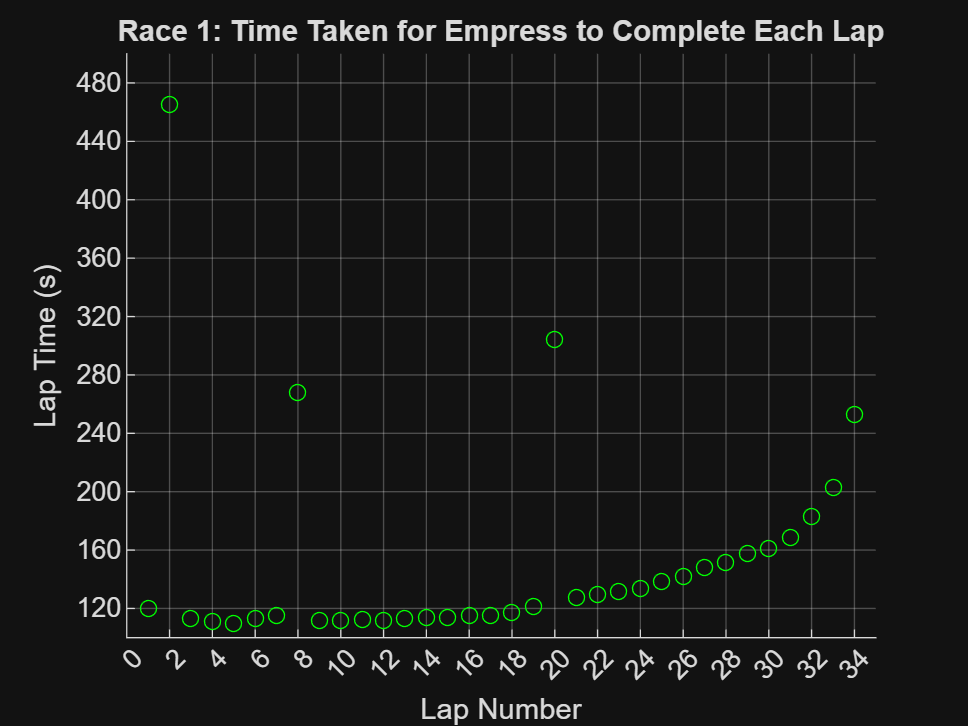

scatter(lapNumber1, lapTime1,"g", "o")
ylabel("Lap Time (s)")
xlabel("Lap Number")
title("Race 1: Time Taken for Empress to Complete Each Lap")
set(gca, "xtick", 0:2:34)
set(gca, "ytick", 0:40:500)
grid on

Graph to display the speed empress had each lap in Race 1:

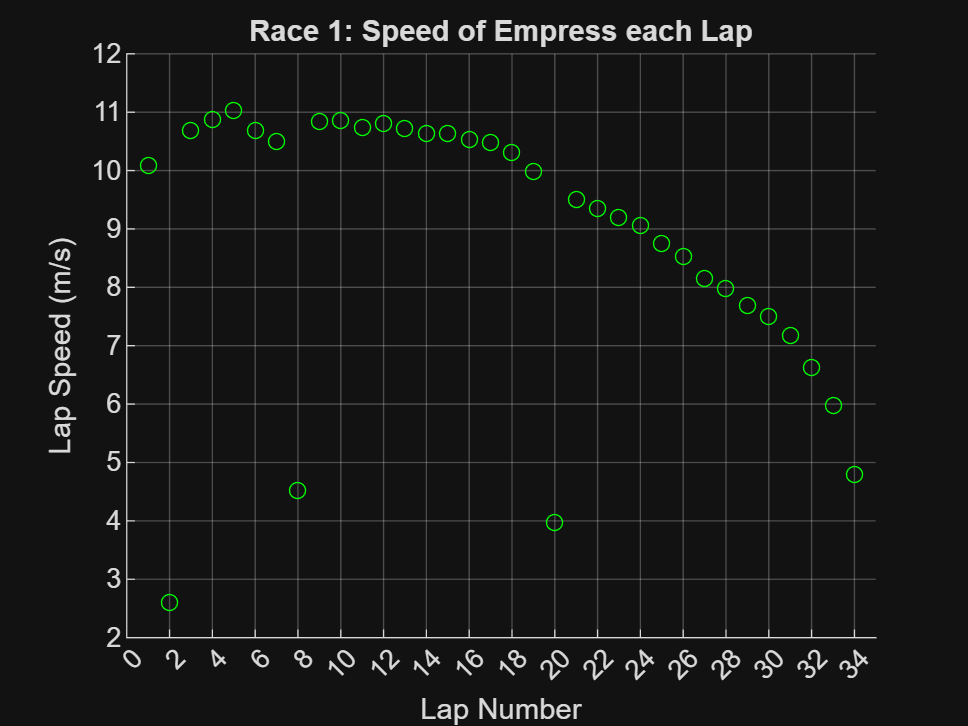

scatter(lapNumber1, eachLapSpeed1,"g", "o")
ylabel("Lap Speed (m/s)")
xlabel("Lap Number")
title("Race 1: Speed of Empress each Lap")
set(gca, "xtick", 0:2:34)
set(gca, "ytick", 0:1:12)
grid on

Graph to display the time taken for empress to complete each lap in Race 2:

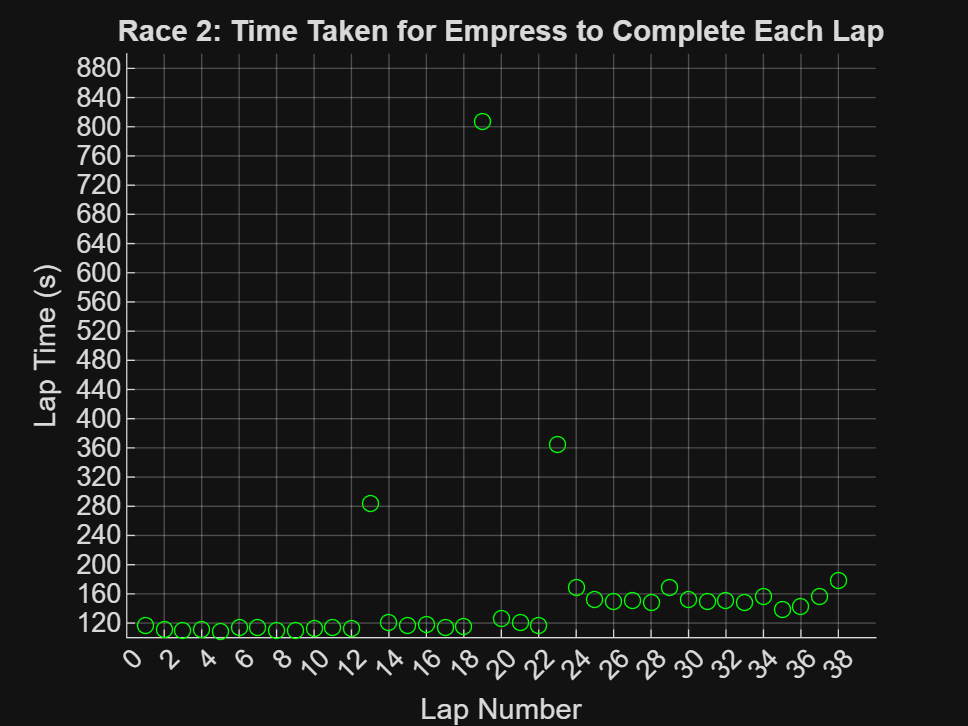

scatter(lapNumber2, lapTime2,"g", "o")
ylabel("Lap Time (s)")
xlabel("Lap Number")
title("Race 2: Time Taken for Empress to Complete Each Lap")
set(gca, "xtick", 0:2:38)
set(gca, "ytick", 0:40:1000)
grid on

Graph to display the speed empress had each lap in Race 2:

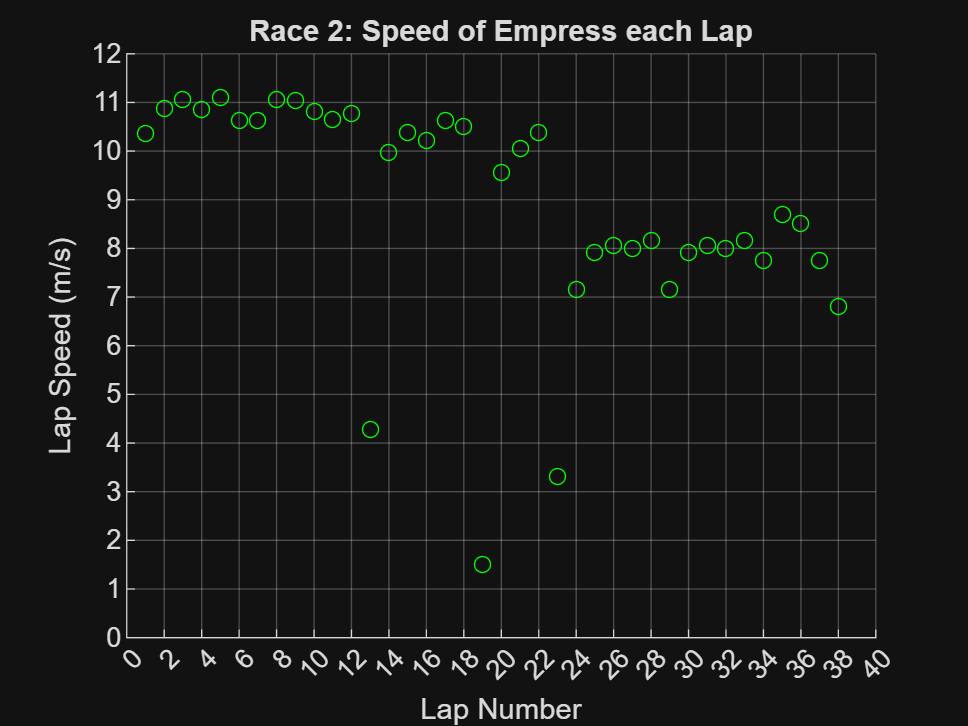

scatter(lapNumber2, eachLapSpeed2,"g", "o")
ylabel("Lap Speed (m/s)")
xlabel("Lap Number")
title("Race 2: Speed of Empress each Lap")
set(gca, "xtick", 0:2:40)
set(gca, "ytick", 0:1:12)
grid on

### **Empress' place in each race:**

Race 1: 16th

Race 2: 11th

### **Analysis of graphs:**

**Race 1:**

**Conclusions from Graph titled "Race 1: Time Taken for Empress to Complete Each Lap": **

The time taken for the car to complete each lap is quite steady around 110seconds (despite some anomalies which are from pit changes) until lap 19 out of 34 where it starts increases at an increasing rate, until it reaches around 250seconds in lap 34. This is more double the initial time taken. 

Therefore, Empress' performance declined. The time taken was quite consistent in one section, but in the second section it increased steadily.

**Conclusions from Graph titled "Race 1: Speed of Empress each Lap": **

The speed of the car is quite constant between 10m/s and 11m/s (despite some anomalies which are from pit changes) until lap 19 out of 34 where it starts to decrease at an increasing rate until it's speed is about 5m/s. This is half the initial speed. 

One area of note that Sophie and I noticed is a dip in speed from lap 5 to 6 and 7 just before a pit change. After this pit change, the speed went back up to it's previous level. This could suggest it would have been better to do the pit change after lap 5 and allow the motor to cool, to remove this dip in speed. However it is difficult to determine where this optimum pit change times could be in races overall. Using an eChook (data logging tool to log current, voltage etc.) during races could help determine this time.

Empress' performance declined. The speed was quite consistent in one section, but in the second section it decreased steadily.

**Race 2:**

**Conclusions from Graph titled "Race 2: Time Taken for Empress to Complete Each Lap": **

The time taken for the car to complete each lap is quite steady around 110 seconds (despite some anomalies from pit changes and one from a red flag, which stopped the race for a period of time) until lap 22 out of 38, where it jumps up to around 180 seconds and remains here until lap 38. This time taken is higher compared to the initial time taken.

Therefore, Empress' performance declined but had consistent time taken split into two different sections.

**Conclusions from Graph titled "Race 2: Speed of Empress each Lap": **

The speed of the car is quite constant between 9.5m/s and 11m/s until lap (despite some anomalies) until lap 22 out of 38 where it jumps up to around 7m/s to 8.5m/s and remains here until lap 38. This speed is lower compared to the initial speed.

Therefore, Empress' performance declined but had consistent speed split into two different sections.

### **Overall analysis:**

**Which race did Empress have a better performance in and why?**

Empress performed better in Race 2.

In race 1, the speed was quite consistent in one section, but in the second section it decreased steadily. In race 2, had consistent speed split into two different sections, where the second section was around a lower speed than the first.

Since Empress was able to maintain more consistency in Race 2, it performed better in race 2. 

Furthermore, in race 1 empress started at 10m/s and finished at 5m/s, but in race 2 empress started at around 10m/s and ended at 8.5m/s. Therefore, Empress performed better in race 2.

One reason why she could have performed well is because the batteries used in the second race had higher Amp-hours. So, more charge was available for the car to use in the second race.

Another reason why she could have performed well is because we realigned the motor sprocket with the axle sprocket between race 1 and 2.

However, this does not provide a clear reason why the speed was more consistent in the second race. Also, it rained in the second race which presumable would cause Empress to move slower because of added resistance. The drivers' apprehension on holding down the power button in fear of crashing the car could also be a factor, which slowed down the car. However, Empress is faster in race 2.

**What was the cause of reduction of speed in both races?**

Saffy, car lead of KM1 (the fastest car our school has), suggested that the decrease in speed in both races is due to the aerodynamics and weight of our car. Our car is not completely streamlined and bullet shaped, which may have caused the speed to be low. Our car's chassis is also quite heavy compared to KM1 because when it was built it was filled with too much resin which made it too heavy. Poor aerodynamics and heavy weight are two factors which would definitely cause the car to be slower. 

A possible solution to this is trying to make our car more aerodynamic by using less structural foam or shaving it down to make the car more sleek.

 We can streamline the vehicle's silhouette by tucking the protruding wheels into the main body.

In regards to the weight of the car we cant change the chassis but we can try and identify and remove unnecessary mass from the car.

**Extra tasks to look into:**

Mr Bamford spoke about how the fastest teams' cars are able alter their motor to their benefit. 

In the car, drivers can turn a dial to reduce their battery charge by one amp-hour when they see a pit sign with this direction during a race. This will reduce their speed but conserve battery for later.

Just before the penultimate lap another pit sign will be shown to direct them to increase their car by one amp hour again, which will give them much more speed in this lap. 

This is desirable because Greenpower count the last lap in the following way. Using an example to explain; say the penultimate lap is 4minutes, the last lap is calculated to be 1/2 of this lap. If the penultimate lap is 2 minutes the last lap is calculated to be 1/4 of this lap. 

Therefore, it is better to have a a shorter amount of time in the penultimate lap than other laps previously in the race, so you can have a short time in the last lap of the race. Perhaps we could add a system to do this to Empress.

Export code and results as a pdf

export("Dunsfold_2026_empress.mlx")

ans = '/MATLAB Drive/Dunsfold_2026_empress.pdf'